addpath("time")

spitzerNEOs_data = readtable('spitzerneos.csv');

AU = astroConstants(2);
a1 = table2array(spitzerNEOs_data(1,5))*AU;
muSun = astroConstants(4);
T = 2*pi*sqrt(a1^3/muSun);           % Orbital Period [s]

coe1 = [a1;
        table2array(spitzerNEOs_data(1,5))*AU;]

% Data extraction from table of EROS ephemeris
eros_data_table = readtable('433_eros.txt');
eros_data = str2double(table2array(eros_data_table(:,5:end)));

% Astronomical constants
AU = astroConstants(2);
muSun = astroConstants(4);

% Indexes corresponding to the correct order of the keplerian elements
% inside the data: [a,e,i,OM,om,th]
idx_coe_in_data_table = [10,1,3,4,5,9]; % [AU,-,deg,deg,deg,deg]
coe_eros = [eros_data(:,idx_coe_in_data_table(1))*AU,...
            eros_data(:,idx_coe_in_data_table(2)),...
            deg2rad(eros_data(:,idx_coe_in_data_table(3))),...
            deg2rad(eros_data(:,idx_coe_in_data_table(4))),...
            deg2rad(eros_data(:,idx_coe_in_data_table(5))),...
            deg2rad(eros_data(:,idx_coe_in_data_table(6)))]; % [km,-,rad,rad,rad,rad]

% Generation of corresponding state vectors
r_eros = zeros(length(coe_eros),3);
v_eros = zeros(length(coe_eros),3);
for i = 1:length(coe_eros)
    [r_eros(i,:), v_eros(i,:)] = sv_from_coe(coe_eros(i,:), muSun);
end


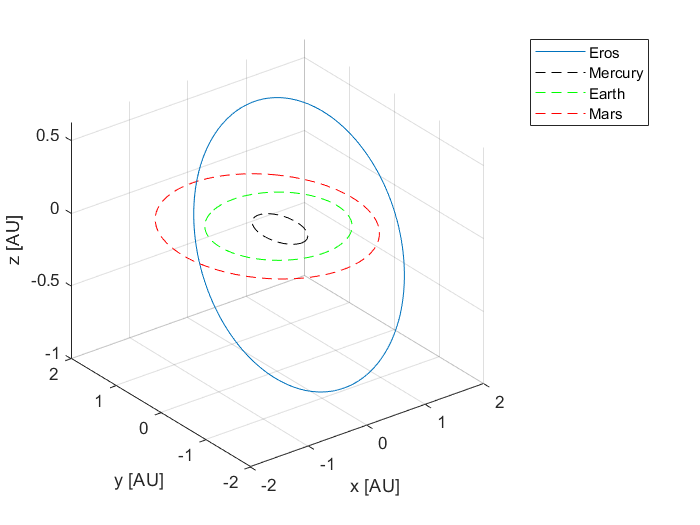

% Plotting the 3D figure
figure('Name','Eros Trajectory')
plot3(r_eros(:,1)./AU, r_eros(:,2)./AU ,r_eros(:,3)./AU )
xlabel('x [AU]'); ylabel('y [AU]');  zlabel('z [AU]'); 
grid on;

% FULL ORBIT IN THE YEAR OF THE ACTUAL ENCOUNTER
date_start_sim = datevec(table2array(eros_data_table(1,3)));
date_end_sim = datevec(table2array(eros_data_table(end,3)));
mjd2000_start_sim = date2mjd2000(date_start_sim);
mjd2000_end_sim = date2mjd2000(date_end_sim);

oneyearME = 88; % one year of Mercury in days
oneyearEA =365; % one year of Earth in days
oneyearMA = 687; % one year of Mars in days

% for full orbit propagation
n=100;
T_ME = linspace(mjd2000_start_sim,mjd2000_start_sim+oneyearME,n);
T_EA = linspace(mjd2000_start_sim,mjd2000_start_sim+oneyearEA,n);
T_MA = linspace(mjd2000_start_sim,mjd2000_start_sim+oneyearMA,n);

for k=1:n
    [kep_ME, muSun] = uplanet(T_ME(k), 1);
    [r_ME, v_ME] = sv_from_coe(kep_ME, muSun);  
    R_ME(k, :) = r_ME;
    V_ME(k, :) = v_ME;
    
    [kep_EA, muSun] = uplanet(T_EA(k), 3);
    [r_EA, v_EA] = sv_from_coe(kep_EA, muSun);  
    R_EA(k, :) = r_EA;
    V_EA(k, :) = v_EA;
    
    [kep_MA, muSun] = uplanet(T_MA(k), 4);
    [r_MA, v_MA] = sv_from_coe(kep_MA, muSun);  
    R_MA(k, :) = r_MA;
    V_MA(k, :) = v_MA;
end

% PLOT ORBITS
hold on
plot3(R_ME(:,1)./AU,R_ME(:,2)./AU,R_ME(:,3)./AU,'--k');
plot3(R_EA(:,1)./AU,R_EA(:,2)./AU,R_EA(:,3)./AU,'--g');
plot3(R_MA(:,1)./AU,R_MA(:,2)./AU,R_MA(:,3)./AU,'--r');

legend('Eros','Mercury','Earth','Mars')